MATLAB Homework 1

Lecturer: Mokshin V.V.

Student: Galimov M.D.

Group № 4167

Kazan, 2019 

**Problem 1. **Generate two sets of 1,000 random numbers that are drawn from the normal distribution (Hint: `randn`).Create a scatter plot of the first set of numbers against the second set of numbers. Label the two axes as "Condition A" and "Condition B". Show the resulting figure.

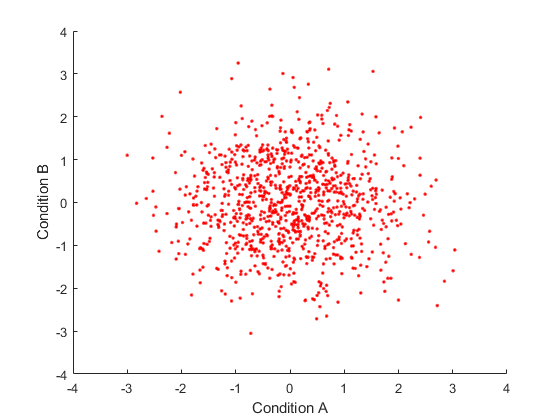

N=1000;
figure;
hold on;
x=randn(1, N);
y=randn(1, N);
h = scatter(x, y, 'r.');
xlabel('Condition A');
ylabel('Condition B');

**Problem 2. **The`data1` variable in Homework1.mat is a matrix of dimensions 2 x 20. Sum the numbers in each rowand then compute the ratio between the two sums (i.e. sum of row 1 divided by sum of row 2). Store the answer in a variable called `result`and echo the value of this variable to the screen.

r_sum = sum(data1, 2);
result = r_sum(1)/r_sum(2)

result = 0.4386

**Problem 3. **The `timeA`,`valsA`, `timeB`,`valsB` variables in Homework1.mat represent time-series data for two signals, A and B. The time points at which A was measured are given in `timeA`, and the corresponding measurements are given in `valsA`. (The same goes for B, `timeB`, and `valsB`.) Create a figure in which both signals are plotted as lines. Use a red line for A and a green line for B. Label the two axes and add a title and legend to the figure. Show the resulting figure.

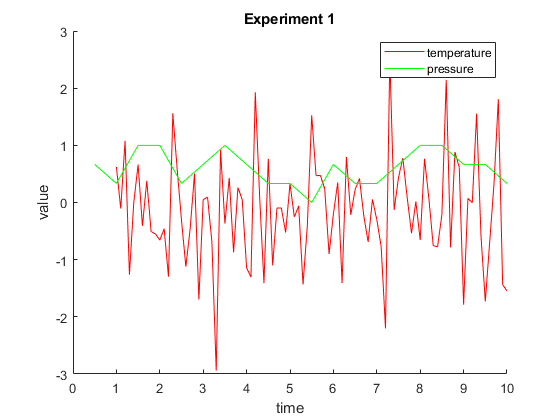

figure;
hold on;
plot(timeA, valsA, 'r');
plot(timeB, valsB, 'g');
xlabel('time');
ylabel('value');
title('Experiment 1');
legend({'temperature', 'pressure'});

**Problem 4. **Create a variable containing the matrix shown to the right. Then, append a new row to the matrix that consists of all 1s. Then, change the top-right element of the matrix to 0. Finally, extract the last column of the matrix and reshape it to be a row vector. Store this vector in a variable called `result g`and echo the value of this variable to the screen.

matrix_1 = [3.0 -1.0 1.5; 2.0 0.0 0.0; 1.0 1.0 1.0];
new_row = [1 1 1];
matrix_1 = [matrix_1; new_row];
matrix_1(1, 3) = 0;
result = matrix_1(:,3)';
result

result =      0     0     1     1


**Problem 5. **Write a function called `checkpositive.m`that accepts a 2D matrix as input and outputs a row vector. The row vector should contain as many elements as there are rows in the 2D matrix, and each element should indicate whether the corresponding row in the 2D matrix contains all positive numbers (use 0 to indicate no and 1 to indicate yes). The function should also report the results to the command window; the report should look something like this:

`Row 1: no Row 2: yes ...etc.`

Finally, in your `homework1.m` script, issue the following commands:

`checkpositive.m`

result = checkpositive([4 1 1; -1 0 0; 0 0 0; .1 .2 .1]);

Row 1: yes
Row 2: no
Row 3: no
Row 4: yes


result

result =      1     0     0     1
